mdot = 9.785;
tspan = linspace(0,3.95);
[t, X] = ode45(@(t,X) ode_func1(t,X,mdot), tspan, [-80 175 900 0]);
Isp = 200;
g_e = 9.81;
T1 = mdot*Isp*g_e;
fprintf("Thrust: %.2f kN\n",T1/1000)

Thrust: 19.20 kN


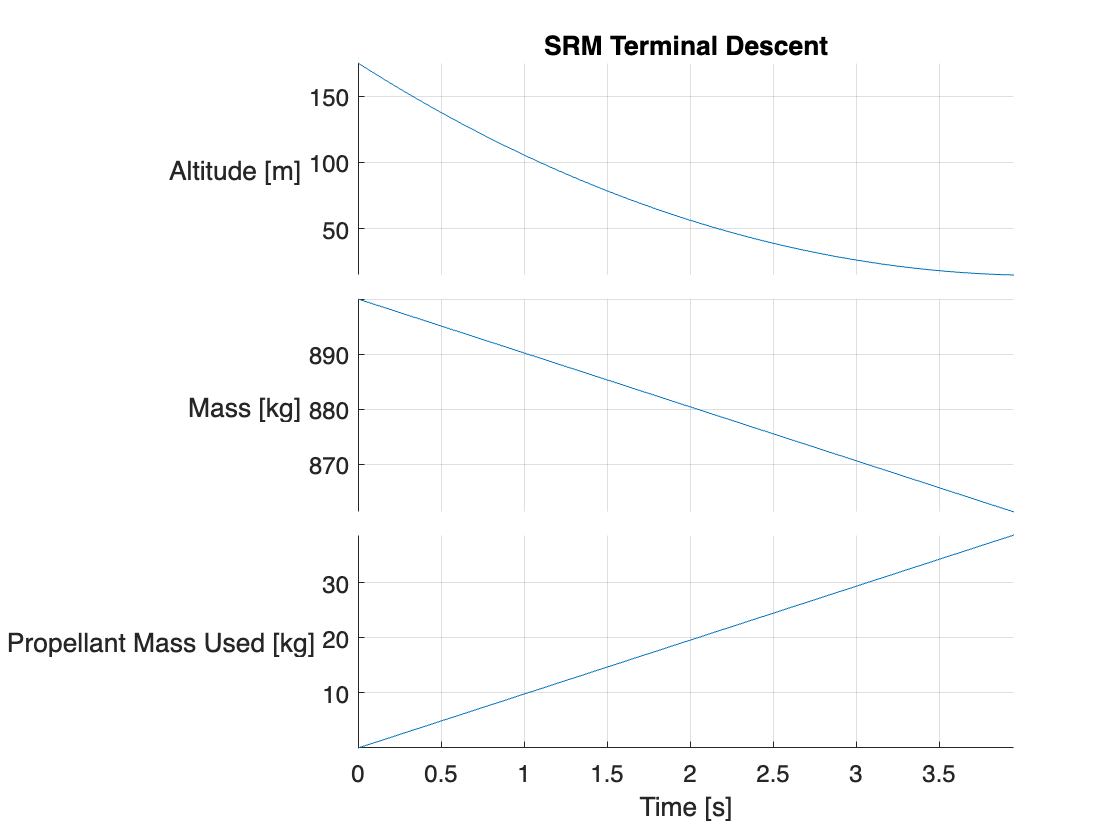

stackedplot(t,X(:,2:4),"Title","SRM Terminal Descent","DisplayLabels",["Altitude [m]" "Mass [kg]" "Propellant Mass Used [kg]"],"XLabel","Time [s]","FontSize",12,"GridVisible","on")

C_D = 0.64;
D = 14.1;
rho0 = 0.012;
H = 7500;
D = @(v,h) pi/8*rho0*exp(-h/H)*C_D*D^2*v^2;

fprintf("Initial Parachute Load: %.2f N\n", D(X(1,1),X(1,2)))

Initial Parachute Load: 3748.92 N


fprintf("Final Parachute Load: %.2f N\n",  D(X(end,1),X(end,2)))

Final Parachute Load: 5.66 N


fprintf("Total Propellant Mass Consumed: %.2f kg",X(end,4))

Total Propellant Mass Consumed: 38.65 kg

mdot = 8.616;
tspan = linspace(0,4.24);
[t, X] = ode45(@(t,X) ode_func2(t,X,mdot), tspan, [-75 175 900 0]);
T2 = mdot*Isp*g_e;
fprintf("Thrust: %.2f kN\n",T2/1000)

Thrust: 16.90 kN


fprintf("Thrust Decrease: %.2f%%\n",(T1 - T2)/T1*100)

Thrust Decrease: 11.95%


function dX = ode_func1(~,X,mdot)
%Constants
C_D = 0.64;
D = 14.1;
Isp = 200;
g_m = 3.74;
g_e = 9.81;
rho0 = 0.012;
H = 7500;

%Variables
v = X(1);
h = X(2);
m_tot = X(3);
m_p = X(4);

%Forces
T = mdot*Isp*g_e;
D = pi/8*rho0*exp(-h/H)*C_D*D^2*v^2;

%Derivatives
dX = zeros(4,1);
dX(1) = D/m_tot + T/m_tot - g_m;
dX(2) = v;
dX(3) = -mdot;
dX(4) = mdot;
end

function dX = ode_func2(~,X,mdot)
%Constants
C_D = 0.64;
D = 14.1;
Isp = 200;
g_m = 3.74;
g_e = 9.81;
rho0 = 0.012;
H = 7500;

%Variables
v = X(1);
h = X(2);
m_tot = X(3);
m_p = X(4);

%Forces
T = mdot*Isp*g_e;
D = 1.25*pi/8*rho0*exp(-h/H)*C_D*D^2*v^2;

%Derivatives
dX = zeros(4,1);
dX(1) = D/m_tot + T/m_tot - g_m;
dX(2) = v;
dX(3) = -mdot;
dX(4) = mdot;
end